load 3.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
f = 0:1e7:4e10;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;
Ia = [0.5 0.7 1 2 3 7.5 14].*1e-3;

I = 0:1e-5:0.04;
c = [57.8774072057481 0.150069586007959 9.69996336936704e-09];
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
T = 273.15 + 20;
U = I.*c(1) + c(2).*log(1 + I./c(3));
load x.mat
Pi = x(1).*(I - x(2) - x(4) - x(5).*(T + (I.*U - P).*x(3) ) - x(6).*(T + (I.*U - P).*x(3) ).^2 - x(7).*(T + (I.*U - P).*x(3) ).^3 - x(8).*(T + (I.*U - P).*x(3) ).^4);



figure
for i = 1:length(Ia)
    I_temp = Ia(i);
    U_temp = U(I == Ia(i));
    P_temp = P(I == Ia(i));
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = 293.15 + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--', 'linewidth',1.7)
    [a, b] = min(abs(M+10));
    temp(i, 1) = Ia(i);
    temp(i, 2) = f(b);
end

错误使用  * 
用于矩阵乘法的维度不正确。请检查并确保第一个矩阵中的列数与第二个矩阵中的行数匹配。要执行按元素相乘，请使用 '.*'。

y_1=[0, 4E10];
y_2=[-10, -10];
plot(y_1,y_2, 'linewidth',1)
axis([0 4E10 -13 20])
legend('0.5mA', '0.7mA', '1mA', '2mA', '3mA', '7.5mA', '14mA')
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig16_1.png');
temp

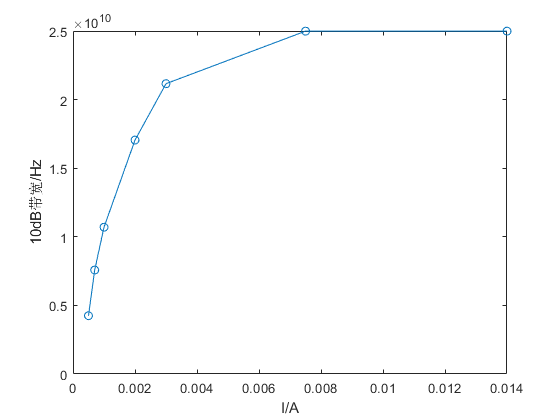

figure
plot(temp(:, 1), temp(:, 2), 'o-')
xlabel('I/A')
ylabel('10dB带宽/Hz')
saveas(gcf, 'fig17.png');

figure
plot(f, S21, 'b')

错误使用 plot
向量长度必须相同。

axis([0 2.5e10 -8 2])
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig14.png');


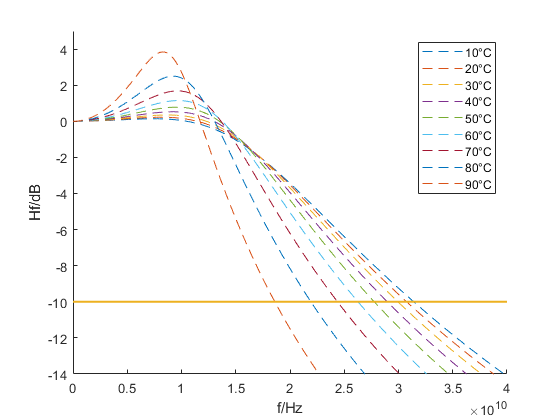


load 3.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
% F = f(1101:end)*1e9;
f = 0:1e7:4e10;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;
Ia = [7.5].*1e-3;
Ta = [10, 20, 30, 40, 50, 60, 70, 80, 90] + 273.15;
figure
for i = 1:length(Ta)
    I_temp = Ia;
    U_temp = U(I == Ia);
    P_temp = P(I == Ia);
    T_temp = Ta(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = T_temp + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(f, M, '--')
end
y_1=[0, 4e10];
y_2=[-10, -10];
plot(y_1,y_2,'linewidth',1.5)
axis([0 4e10 -14 5])
legend('10°C', '20°C', '30°C', '40°C', '50°C', '60°C', '70°C', '80°C', '90°C');
xlabel('f/Hz')
ylabel('Hf/dB')
saveas(gcf, 'fig18.png');

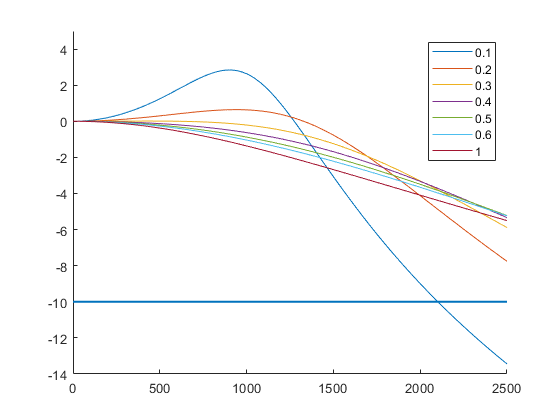

load 3.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;
Ia = [7.5].*1e-3;
Ta = [20] + 273.15;
eta = [0.1 0.2 0.3 0.4 0.5 0.6 1];
figure
for i = 1:length(eta)
    I_temp = Ia;
    U_temp = U(I == Ia);
    P_temp = P(I == Ia);
    T_temp = Ta;
    x(1) = eta(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = T_temp + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(M)
end
y_1=[0, 2500];
y_2=[-10, -10];
plot(y_1,y_2,'linewidth',1.5)
axis([0 2500 -14 5])
legend('0.1', '0.2', '0.3', '0.4', '0.5', '0.6', '1');

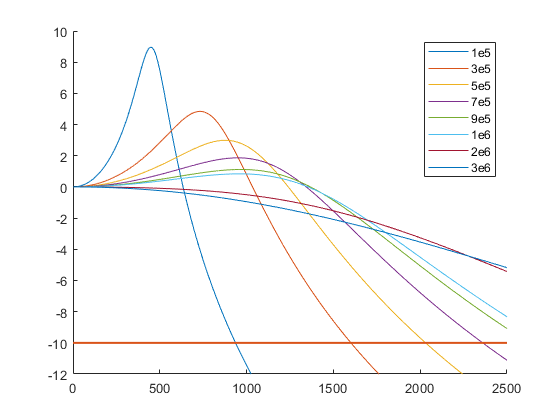

load 3.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;
Ia = [7.5].*1e-3;
Ta = [20] + 273.15;
G0 = [1e5 3e5 5e5 7e5 9e5 1e6 2e6 3e6];
figure
for i = 1:length(G0)
    I_temp = Ia;
    U_temp = U(I == Ia);
    P_temp = P(I == Ia);
    T_temp = Ta;
    x(5) = G0(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = T_temp + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(M)
end
y_1=[0, 2500];
y_2=[-10, -10];
plot(y_1,y_2,'linewidth',1.5)
axis([0 2500 -12 10])
legend('1e5', '3e5', '5e5', '7e5', '9e5', '1e6', '2e6', '3e6');

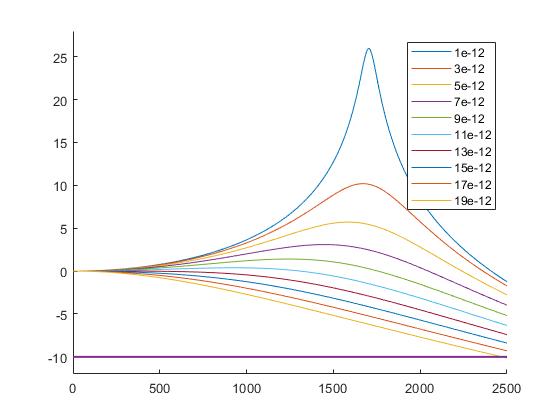

load 3.mat
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\S21_5.mat')
F = f(1101:end)*1e9;
Hf = S21(1101:end);
P = P/1000;
P(P==0) = 2.56043051100000e-07; 
I = I/1000;
U = U;
% x = target;
init = [0.7, 1E-5, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
% init = [0.7, 100, 9.6E-9, 1.5E-8, 1.8E6, 4.97E5, 3.8E-12, 4.7E-8];
lambda = 0.327974911948322;
q = 1.6E-19;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
T =  293.15 + (I.*U - P).*Rth;
Ioff = a_0 + a_1.*T + a_2.*T.^2 + a_3.*T.^3 + a_4.*T.^4;
Ns = (P./(x(4).*x(7)) + x(5).*x(6).*P./(x(4) + x(8).*P))./(x(2)./x(3) + x(5).*P./(x(4) + x(8).*P));
test1 = q.*(Ns./x(3) + x(5).*(Ns - x(6)).*P./(x(4) + x(8).*P))./x(1) + Ith0 + Ioff - I;
test1 = test1;

Ss = ((x(1).*(I - Ith0 - Ioff)./q) - (Ns./x(3)))./(x(5).*(Ns - x(6)));
Ps = x(4).*Ss;
test2 = Ps - P;
test2 = test2./Ps;
Ia = [7.5].*1e-3;
Ta = [20] + 273.15;
tp = [1 3 5 7 9 11 13 15 17 19].*1e-12;
figure
for i = 1:length(tp)
    I_temp = Ia;
    U_temp = U(I == Ia);
    P_temp = P(I == Ia);
    T_temp = Ta;
    x(7) = tp(i);
    Ns1 = (P_temp./(x(4).*x(7)) + x(5).*x(6).*P_temp./(x(4) + x(8).*P_temp))./(x(2)./x(3) + x(5).*P_temp./(x(4) + x(8).*P_temp));
    T1 = T_temp + (I_temp.*U_temp - P_temp).*Rth;
    Ioff1 = a_0 + a_1.*T1 + a_2.*T1.^2 + a_3.*T1.^3 + a_4.*T1.^4;
    Ss1 = ((x(1).*(I_temp - Ith0 - Ioff1)./q) - (Ns1./x(3)))./(x(5).*(Ns1 - x(6)));
    Ps1 = x(4).*Ss1;
    Y = 1./x(7) + 1./x(3) + x(5).*Ps1./(x(4) + x(8).*Ps1) - x(5).*(Ns1 - x(6))./(1 + x(8).*Ps1./x(4)).^2; %% 是否平方
    Z = 1./(x(7).*x(3)) + x(5).*Ps1./(x(7).*(x(4) + x(8).*Ps1)) - (1 - x(2)).*x(5).*(Ns1 - x(6))./(x(3).*(1 + x(8).*Ps1./x(4)).^2); %% 是否平方
    H=Z./((2i*pi*f).^2+(2i*pi*f)*Y+Z);
    M=20*log10(abs(H));
    hold on
    plot(M)
end
y_1=[0, 2500];
y_2=[-10, -10];
plot(y_1,y_2,'linewidth',1.5)
axis([0 2500 -12 28])
legend('1e-12', '3e-12', '5e-12', '7e-12', '9e-12', '11e-12', '13e-12', '15e-12', '17e-12', '19e-12');